hold on;
grid on;
x = [4.8, 3, 1.5];
y = [7, 4.6, 2.3];
scatter(x,y);
xlabel('I_p, мА')
ylabel("n_i \cdot 10^{16}, м^{-3}")
title("График зависимости концентрации электронов от тока разряда")
xlim([0,5])
coeff_3 = polyfit(x,y,1)

coeff_3 =     1.4212    0.2275


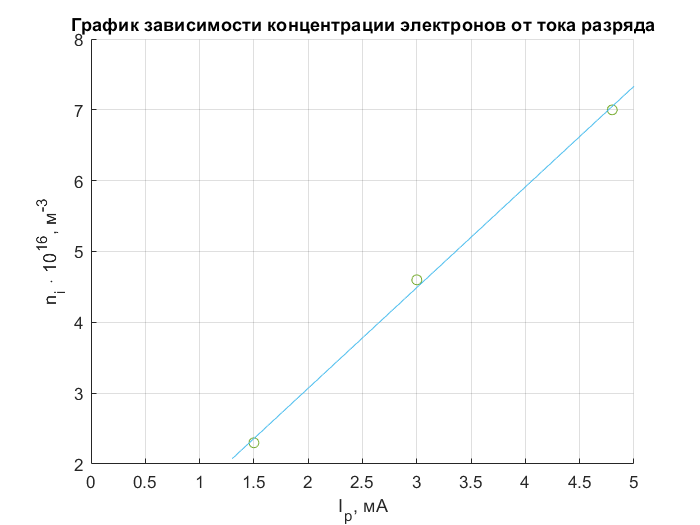

y1 = 0;
xi = min(1.3):0.1:max(5);
for k=0:1
    y1 = y1 + coeff_3(1-k+1) * xi.^k;
end
gr_3 = plot(xi, y1);